# Imitate MPC Controller for Lane Keeping Assist

This example shows how to train, validate, and test a deep neural network that imitates the behavior of a model predictive controller for an automotive lane keeping assist system. In the example, you also compare the behavior of the deep neural network with that of the original controller.

Model predictive control (MPC) solves a constrained quadratic-programming (QP) optimization problem in real time based on the current state of the plant. Because MPC solves its optimization problem in an open-loop fashion, you can potentially replace the controller with a deep neural network. Evaluating a deep neural network is more computationally efficient than solving a QP problem in real time.

If the training of the network sufficiently traverses the state-space for the application, you can create a reasonable approximation of the controller behavior. You can then deploy the network for your control application. You can also use the network as a warm starting point for training the actor network of a reinforcement learning agent. For an example, see [Train DDPG Agent with Pretrained Actor Network](docid:rl_ug#mw_81cf3091-94f1-403e-a4e1-da75c4d2e6de).

## Design MPC Controller

Design an MPC controller for lane keeping assist. To do so, first create a dynamic model for the vehicle.

% [sys,Vx] = createModelForMPCImLKA;

Create and design the MPC controller object `mpcobj`. Also, create an `mpcstate` object for setting the initial controller state. For details on the controller design, type `edit createMPCobjImLKA`.

% [mpcobj,initialState] = createMPCobjImLKA(sys);

For more information on designing model predictive controllers for lane keeping assist applications, see [Lane Keeping Assist System Using Model Predictive Control](docid:mpc_ug#mw_a74af043-f834-4024-ae3a-ab934fdf6031) and [Lane Keeping Assist with Lane Detection](docid:mpc_ug#mw_58bd8d15-b052-495d-afe9-77b7bf20fac4).

## Prepare Input Data

Load the input data from `InputDataFileImLKA.mat`. The columns of the data set follow:

- Lateral velocity $V_y$

- Yaw angle rate $r$

- Lateral deviation $e_1$

- Relative yaw angle $e_2$

- Previous steering angle (control variable) $u$

- Measured disturbance (road yaw rate: longitudinal velocity * curvature ($\rho$))

- Cost function value

- MPC iterations

- Steering angle computed by MPC controller: $u^*$

The data in `InputDataFileImLKA.mat` was created by computing the MPC control action for randomly generated states, previous control actions, and measured disturbances. To generate your own training data, use the `collectDataImLKA` function.

Load the input data.

% dataStruct = load('InputDataFileImLKA.mat');
dataStruct = load('./exampleTrajectories4.mat');
data = dataStruct.trajectories;
data = reshape(data, [1000 * 1000, 9]);

dataStruct2 = load('./new_exp_trajectories.mat');
data2 = dataStruct2.trajectories;
data2 = reshape(data2, [1000 * 1000, 9]);

Divide the input data into training, validation, and testing data. First, determine the number of validation data rows based on a given percentage.

totalRows = size(data,1);
validationSplitPercent = 0.1;
numValidationDataRows = floor(validationSplitPercent*totalRows);

Determine the number of test data rows based on a given percentage.

testSplitPercent = 0.05;
numTestDataRows = floor(testSplitPercent*totalRows);

Randomly extract validation and testing data from the input data set. To do so, first randomly extract enough rows for both data sets.

randomIdx = randperm(totalRows,numValidationDataRows + numTestDataRows);
randomData = data(randomIdx,:);

randomData2 = data2(randomIdx, :);

Divide the random data into validation and testing data.

validationData = randomData(1:numValidationDataRows,:);
testData = randomData(numValidationDataRows + 1:end,:);

validationData2 = randomData2(1:numValidationDataRows,:);
testData2 = randomData2(numValidationDataRows + 1:end,:);

Extract the remaining rows as training data.

trainDataIdx = setdiff(1:totalRows,randomIdx);
trainData = data(trainDataIdx,:);

trainData2 = data2(trainDataIdx, :)

Randomize the training data.

numTrainDataRows = size(trainData,1);
shuffleIdx = randperm(numTrainDataRows);
shuffledTrainData = trainData(shuffleIdx,:);

Reshape the training and validation data into 4-D matrices for use with `trainNetwork`.

numObservations = 6; 
numActions = 1;

trainInput = shuffledTrainData(:,[1:5, 7]);
trainOutput = shuffledTrainData(:,6);



validationInput = validationData(:,[1:5, 7]);
validationOutput = validationData(:,6);
validationCellArray = {validationInput,validationOutput};

Reshape the testing data for use with `predict`.

testDataInput = testData(:,1:6);
testDataOutput = testData(:,9);

## Create Deep Neural Network

The deep neural network architecture uses the following layers.

- `imageInputLayer` is the input layer of the neural network.  

- `fullyConnectedLayer` multiplies the input by a weight matrix and then adds a bias vector. 

- `reluLayer` is the activation function of the neural network. 

- `tanhLayer` constrains the value to the range to [-1,1].

- `scalingLayer` scales the value to the range to [-1.04,1.04], this constrains the steering angle to the range [-60,60].

- `regressionLayer` defines the loss function of the neural network.

Create the deep neural network that will imitate the MPC controller after training.

% imitateMPCNetwork = [
%     featureInputLayer(numObservations,'Normalization','none','Name','InputLayer')    
%     fullyConnectedLayer(45,'Name','Fc1')
%     reluLayer('Name','Relu1')
%     fullyConnectedLayer(45,'Name','Fc2')
%     reluLayer('Name','Relu2')    
%     fullyConnectedLayer(45,'Name','Fc3')
%     reluLayer('Name','Relu3')     
%     fullyConnectedLayer(numActions,'Name','OutputLayer')
%     tanhLayer('Name','Tanh1')    
%     scalingLayer('Name','Scale1','Scale',1.04)    
%     regressionLayer('Name','RegressionOutput')
% ];


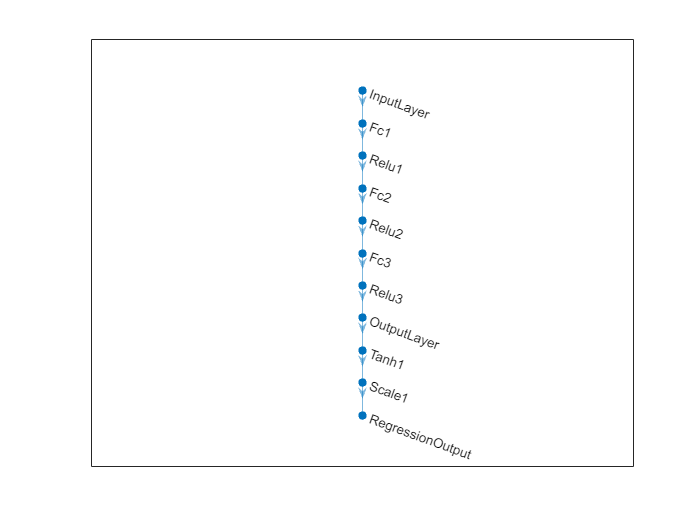

% generator
nI = 6;  % number of inputs (6)

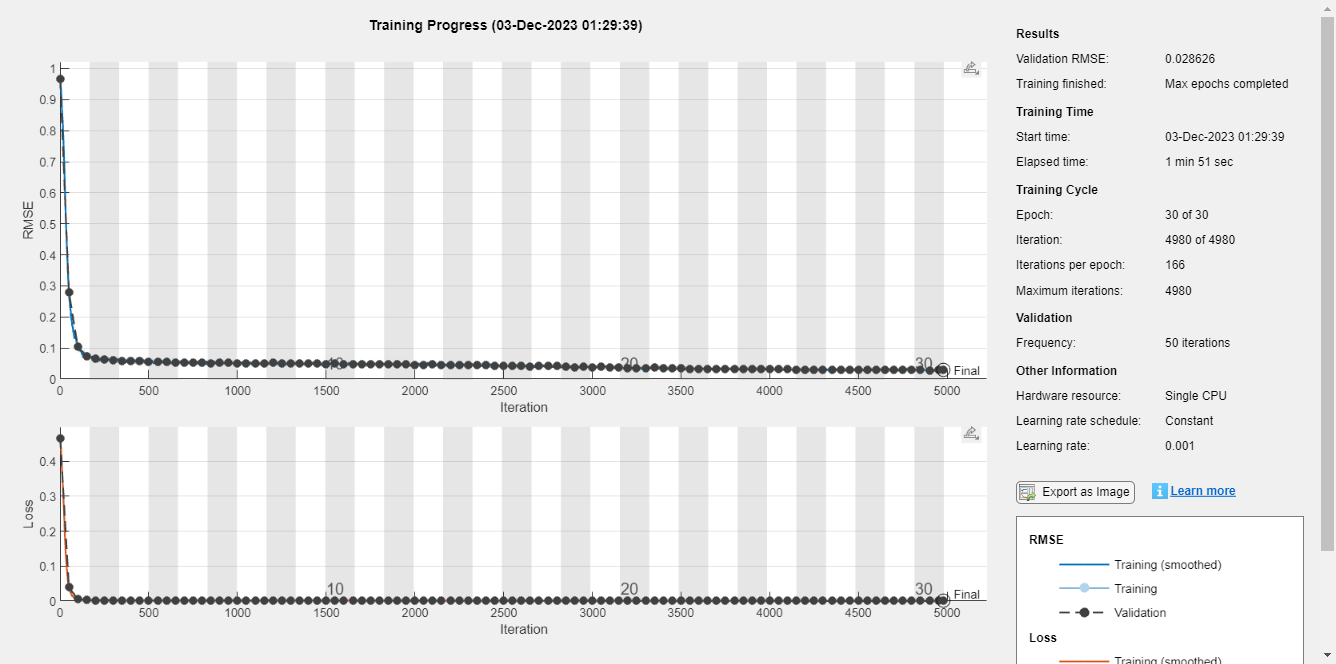

nL = 24;                            % number of neurons
nO = 31;    % number of outputs (31) - evenly spaced angles between -theta_max and theta_max

% policy_net = [
%     featureInputLayer(numObservations,'Normalization','none','Name','InputLayer')    
%     fullyConnectedLayer(45,'Name','Fc1')
%     reluLayer('Name','Relu1')       
%     fullyConnectedLayer(1,'Name','OutputLayer')
%     tanhLayer('Name','Tanh1')    
%     scalingLayer('Name','Scale1','Scale',1.04)    
%     RegressionLayer('Name','RegressionOutput') % don't worry about softmax, directly predict the angle
% ];nLayer('Name','RegressionOutput')
% 
% policy_net_prob = [
%     featureInputLayer(numObservations,'Normalization','none','Name','InputLayer')    
%     fullyConnectedLayer(45,'Name','Fc1')
%     reluLayer('Name','Relu1')       
%     fullyConnectedLayer(nO,'Name','OutputLayer')    
%     softmaxLayer('Name','SoftmaxOutput') % don't worry about softmax, directly predict the angle
% ];nLayer('Name','SoftmaxOutput') % remember to take argmax using [~, idx] = max(output)

% 
% value_net = [
%     featureInputLayer(numObservations,'Normalization','none','Name','InputLayer')    
%     fullyConnectedLayer(45,'Name','Fc1')
%     reluLayer('Name','Relu1')
%     fullyConnectedLayer(1,'Name','OutputLayer')
%     reluLayer('Name','Relu2')
%     regressionLayer('Name','RegressionOutput') % directly predict the value
% ];nLayer('Name','RegressionOutput')


% action = @get_action;
% % reward = @get_reward;
% 
% function [action, v_pred] = get_action(obj, obs, stochastic)
%     action = predict(policy_net,testDataInput); % adjust based on actual input from the Matlab example
%     v_pred = predict(value_net,testDataInput);
% end

generator = [
    featureInputLayer(numObservations,'Normalization','none','Name','InputLayer')    
    fullyConnectedLayer(45,'Name','Fc1')
    reluLayer('Name','Relu1')          

Test Data RMSE = 2.926389e-02


    fullyConnectedLayer(1,'Name','OutputLayer')
    tanhLayer('Name','Tanh1')    
    scalingLayer('Name','Scale1','Scale',1.04)    
    RegressionLayer('Name','RegressionOutput')
];nLayer('Name','RegressionOutputSteeringAngle') % remember to take argmax using [~, idx] = max(output)

dicriminator = [
    featureInputLayer(numObservations,'Normalization','none','Name','InputLayer')    
    fullyConnectedLayer(45,'Name','Fc1')
    reluLayer('Name','Relu1')       
    fullyConnectedLayer(1,'Name','OutputLayer')    
    sigmoidLayer('Name','SoftmaxOutput') % don't worry about softmax, directly predict the angle
];nLayer('Name','ProbabilityScore') % remember to take argmax using [~, idx] = max(output)

% generate 2 different trajectories from the MPC expert
% call 1 (exampleTrajectories4.mat) the state with actions 

Plot the network.

plot(layerGraph(generator))
plot(layerGraph(discriminator))

## Train Deep Neural Network

Specify training options.


options = trainingOptions('adam', ...
    'Verbose',false, ...
    'Plots','training-progress', ...
    'Shuffle','every-epoch', ...
    'MaxEpochs', 30, ...
    'MiniBatchSize',512, ...
    'ValidationData',validationCellArray, ...
    'InitialLearnRate',1e-3, ...
    'GradientThresholdMethod','absolute-value', ...
    'ExecutionEnvironment','cpu', ...
    'GradientThreshold',10, ...
    'Epsilon',1e-8);

Train the deep neural network. To view detailed training information in the Command Window, set the `Verbose` training option to `true`.

imitateMPCNetObj = trainNetwork(trainInput,trainOutput,imitateMPCNetwork,options);

Training of the deep neural network stops after the final iteration.

The training and validation loss are nearly the same for each mini-batch, which indicates that the trained network does not overfit.

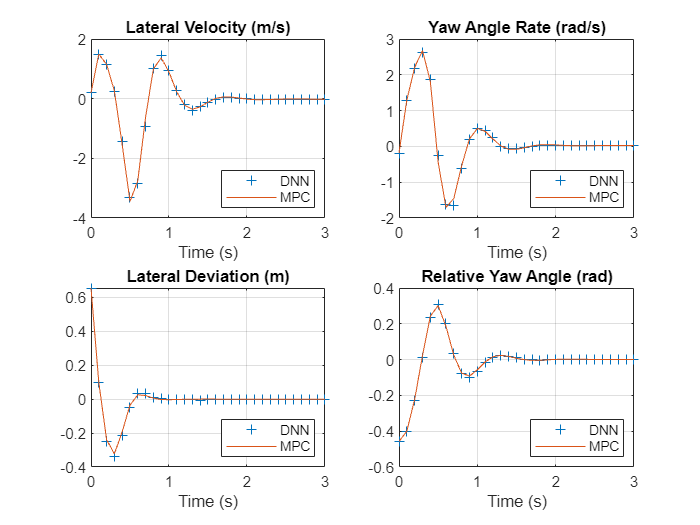

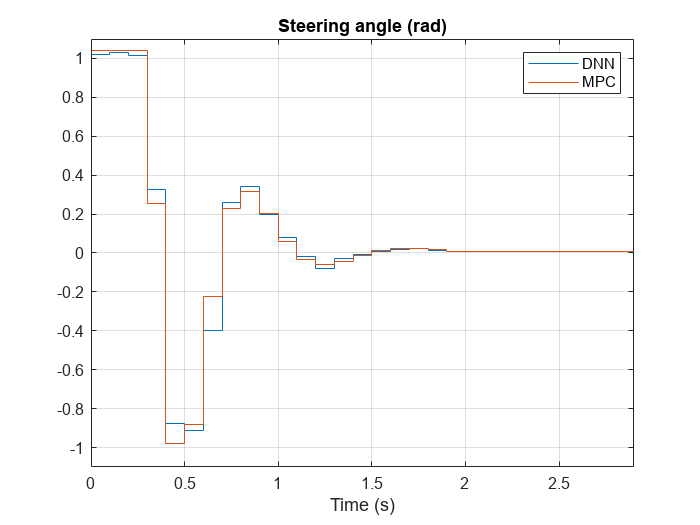

generator = dlnetwork(generator);
discriminator = dlnetwork(discriminator)

numEpochs = 500;
miniBatchSize = 128;

learnRate = 0.0002;
gradientDecayFactor = 0.5;
squaredGradientDecayFactor = 0.999;

flipProb = 0.35;
validationFrequency = 100;

adsXTrain = arrayDatastore(trainInput,OutputType="same");
adsTTrain = arrayDatastore(trainOutput);
cdsTrain = combine(adsXTrain,adsTTrain);


% GAIL algorithm
function trained_policy = train_gail(epochs, batch_size, expert_demo_episodes, update_ratio)
    % Optimizers
    discriminator_optimizer = adamupdate(adam(0.001), discriminator.model.Learnables, discriminator.model.Grads);
    generator_optimizer = adamupdate(adam(0.001), generator.model.Learnables, generator.model.Grads);

    % Pre-train discriminator with expert demonstrations
    expert_states = [];
    for i = 1:expert_demo_episodes
        state = env.reset();
        done = false;
        while ~done
            action = randi(action_dim); % random action for demonstration
            expert_states = [expert_states; state];
            [state, ~, done, ~] = env.step(action);
        end
    end

    expert_states = single(expert_states);
    expert_labels = ones(size(expert_states, 1), 1, 'single');

    for epoch = 1:epochs
        % Train discriminator
        sampled_states = [];
        sampled_actions = [];
        for i = 1:batch_size
            state = env.reset();
            done = false;
            while ~done
                action_prob = predict(generator.model, single(state));
                action = randsample(1:action_dim, 1, true, action_prob);
                sampled_states = [sampled_states; state];
                sampled_actions = [sampled_actions; action];
                [state, ~, done, ~] = env.step(action);
            end
        end

        sampled_states = single(sampled_states);
        sampled_actions = single(sampled_actions);
        fake_labels = zeros(size(sampled_states, 1), 1, 'single');
        discriminator_loss = bce(discriminator.forward(sampled_states), fake_labels);
        [discriminator_optimizer, discriminator_loss] = update(discriminator_optimizer, discriminator_loss);

        discriminator_loss = bce(discriminator.forward(expert_states), expert_labels);
        [discriminator_optimizer, discriminator_loss] = update(discriminator_optimizer, discriminator_loss);

        % Train generator
        generator_loss = crossentropy(generator.forward(sampled_states), sampled_actions);
        [generator_optimizer, generator_loss] = update(generator_optimizer, generator_loss);

        % Update discriminator more frequently than generator
        if mod(epoch, update_ratio) == 0
            for i = 1:update_ratio
                discriminator_loss = bce(discriminator.forward(sampled_states), fake_labels);
                [discriminator_optimizer, discriminator_loss] = update(discriminator_optimizer, discriminator_loss);

                discriminator_loss = bce(discriminator.forward(expert_states), expert_labels);
                [discriminator_optimizer, discriminator_loss] = update(discriminator_optimizer, discriminator_loss);
            end
        end

        if mod(epoch, 10) == 0
            fprintf('Epoch: %d, Discriminator Loss: %.4f, Generator Loss: %.4f\n', epoch, gather(discriminator_loss), gather(generator_loss));
        end
    end

    % Extract the generator for testing
    trained_policy = copy(generator);
end

% Training the GAIL model
trained_policy = train_gail(1000, 32, 100, 0.8);

% Testing the trained policy
state = env.reset();
done = false;
total_reward = 0;
while ~done
    action_prob = predict(trained_policy.model, single(state));
    action = randsample(1:action_dim, 1, true, action_prob);
    [state, reward, done, ~] = env.step(action);
    total_reward = total_reward + reward;
end

fprintf('Total Reward: %.4f\n', total_reward);

% Close the environment
env.close();


## Test Trained Network

Check that the trained deep neural network returns steering angles similar to the MPC controller control actions given the test input data. Compute the network output using the `predict` function.

predictedTestDataOutput = predict(imitateMPCNetObj,testDataInput);

Calculate the root mean squared error (RMSE) between the network output and the testing data.

testRMSE = sqrt(mean((testDataOutput - predictedTestDataOutput).^2));
fprintf('Test Data RMSE = %d\n', testRMSE);

The small RMSE value indicates that the network outputs closely reproduce the MPC controller outputs.

## Compare Trained Network with MPC Controller

To compare the performance of the MPC controller and the trained deep neural network, run closed-loop simulations using the vehicle plant model.

Generate random initial conditions for the vehicle that are not part of the original input data set, with values selected from the following ranges:

- Lateral velocity $V_y$ — Range (-2,2) m/s

- Yaw angle rate $r$ — Range (-1.04,1.04) rad/s

- Lateral deviation $e_1$ — Range (-1,1) m

- Relative yaw angle $e_2$ — Range (-0.8,0.8) rad

- Last steering angle (control variable) $u$ — Range (-1.04,1.04) rad

- Measured disturbance (road yaw rate, defined as longitudinal velocity * curvature ($\rho$)) — Range (-0.01,0.01) with a minimum road radius of 100 m

rng(5e7)
[x0,u0,rho] = generateRandomDataImLKA(data);

Set the initial plant state and control action in the `mpcstate` object.

initialState.Plant = x0;
initialState.LastMove = u0;

Extract the sample time from the MPC controller. Also, set the number of simulation steps.

Ts = mpcobj.Ts;
Tsteps = 30;     

Obtain the `A` and `B` state-space matrices for the vehicle model.

A = sys.A;
B = sys.B;

Initialize the state and input trajectories for the MPC controller simulation.

xHistoryMPC = repmat(x0',Tsteps+1,1);
uHistoryMPC = repmat(u0',Tsteps,1);

Run a closed-loop simulation of the MPC controller and the plant using the `mpcmove` function.

for k = 1:Tsteps
    % Obtain plant output measurements, which correspond to the plant outputs.
    xk = xHistoryMPC(k,:)';
    % Compute the next cotnrol action using the MPC controller.
    uk = mpcmove(mpcobj,initialState,xk,zeros(1,4),Vx*rho);
    % Store the control action.
    uHistoryMPC(k,:) = uk;
    % Update the state using the control action.
    xHistoryMPC(k+1,:) = (A*xk + B*[uk;Vx*rho])';
end

Initialize the state and input trajectories for the deep neural network simulation.     

xHistoryDNN = repmat(x0',Tsteps+1,1);
uHistoryDNN = repmat(u0',Tsteps,1);
lastMV = u0;

Run a closed-loop simulation of the trained network and the plant. The `neuralnetLKAmove` function computes the deep neural network output using the `predict` function. 

for k = 1:Tsteps
    % Obtain plant output measurements, which correspond to the plant outputs.
    xk = xHistoryDNN(k,:)';
    % Predict the next move using the trained deep neural network.
    uk = neuralnetLKAmove(imitateMPCNetObj,xk,lastMV,rho);
    % Store the control action and update the last MV for the next step.
    uHistoryDNN(k,:) = uk;
    lastMV = uk;
    % Update the state using the control action.
    xHistoryDNN(k+1,:) = (A*xk + B*[uk;Vx*rho])';
end

Plot the results to compare the MPC controller and trained deep neural network (DNN) trajectories.

plotValidationResultsImLKA(Ts,xHistoryDNN,uHistoryDNN,xHistoryMPC,uHistoryMPC);

The deep neural network successfully imitates the behavior of the MPC controller. The vehicle state and control action trajectories for the controller and the deep neural network closely align.

*Copyright 2020 The MathWorks, Inc.*